clc,clear,close all

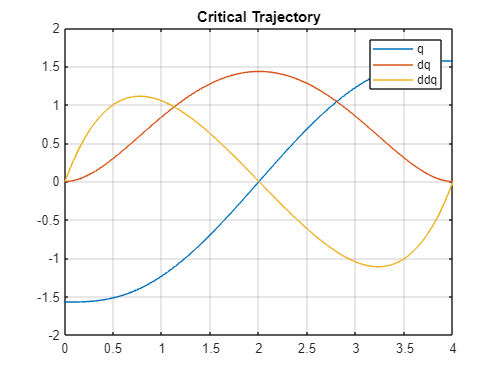

% Dynamical Model of two link Planar Manupulator 

% motor properties
amax=1.05; %[rad/s^2]
mm = [0.3, 0.3];
Im = [54e-6, 54e-6]; %[kg/m^2]
kr = [1/10,1/5];
%kr = [1,1];

% link dimension
lx=[0.20 0.20]; % m
ly=[0.06 0.06]; % m
lz=[0.01 0.01]; % m

%material properties
density=2660; % [kg/m3] AW 5083 alloy
%rho=(density*1000)/100^3; %[g/cm3]
rho = density; 

mass=[rho*lx(1)*ly(1)*lz(1) rho*lx(2)*ly(2)*lz(2)];

% simulation parameters
methods = dynlib;
Tf = 4;
t_step = 0.01;
[A, ~] = methods.criticaltrajectory(Tf, amax);
t = [0:0.01:Tf];
qd = [];

for i=1:length(t)
    qd=[qd;A'*methods.vand(t(i), 7)', A'*methods.devand(t(i),7)', A'*methods.dedevand(t(i),7)'];
end

figure
plot(t, qd);
legend('q', 'dq','ddq');
title('Critical Trajectory');
grid on;


% TODO: Friction?
F = [0 0; 0 0]; % TEMP

% Initial Values

q0 = [-pi/2;-pi/2];
dq0 = [0;0];
ddq0 = [0;0];

%controller variables
%Kp = diag([ 15 15 ]);
%Kd = diag([ 32 32 ]);

val=[1 1];
Kp=diag((val.^2)./2);
Kd=diag(val);
%wry 